# Simulate AUTOSAR Basic Software Services and Run-Time Environment

Simulate AUTOSAR component calls to Basic Software memory and diagnostic services by using reference implementations.

## Configure Calls to AUTOSAR Basic Software Services

The AUTOSAR standard defines Basic Software (BSW) services that run in the AUTOSAR run-time environment. The services include NVRAM Manager (NvM) Diagnostic Event Manager (Dem), and Function Inhibition Manager (FiM) services. In the AUTOSAR run-time environment, AUTOSAR software components typically access BSW services using client-server or sender-receiver communication.

In your AUTOSAR software component model, to implement client calls to NvM, Dem, and FiM service interfaces, you drag and drop preconfigured NvM, Dem, and FiM caller blocks. Each block has prepopulated parameters, such as **Client port name **and **Operation**. You configure the block parameters, for example, to select a service operation to call. To configure the added caller blocks in the AUTOSAR software component, you synchronize the model. The software creates AUTOSAR client-service interfaces, operations, and ports, and maps each Simulink function call to an AUTOSAR client port and operation. For more information, see [Configure Calls to AUTOSAR NVRAM Manager Service](docid:autosar_ug.bvh7all-1), [Configure Calls to AUTOSAR Diagnostic Event Manager Service](docid:autosar_ug.bvfx3up-1), and [Configure Calls to AUTOSAR Function Inhibition Manager Service](docid:autosar_ug.mw_a0e9dace-a451-4695-912b-de28eff43dd6).

Here is a throttle position integration model, which integrates two throttle position sensor components and a throttle position monitor component. The sensor components take a raw throttle position sensor (TPS) value and convert it to a TPS percent value. The monitor component takes the TPS percent values provided by the primary and secondary sensor components and decides which TPS signal to pass through. The sensor components call BSW NvM and Dem services, and the monitor component calls BSW Dem services.

open_system('autosar_bsw_presim');

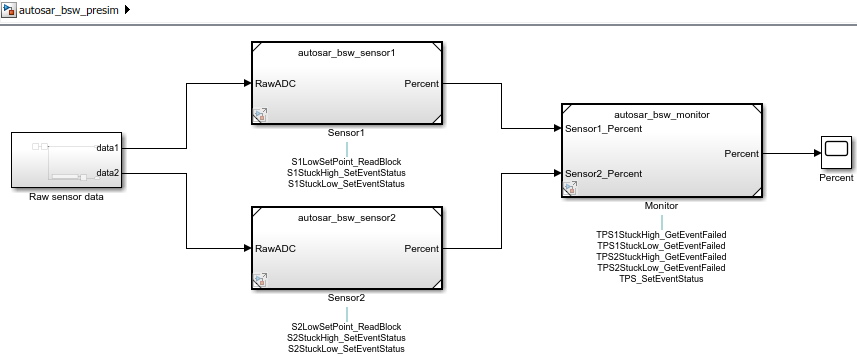

Sensor components `autosar_bsw_sensor1` and `autosar_bsw_sensor2` each contain an Initialize Function block, which calls the NvM service interface `NvMService`. The calls are implemented using the Basic Software library block [NvMServiceCaller](docid:autosar_ref.bvczlrr-1). Each block is configured to call the `NvMService` operation `ReadBlock`. The `ReadBlock` calls use client ports `S1LowSetPoint` and `S2LowSetPoint`. Here is the Initialize Function block for `autosar_bsw_sensor1`.

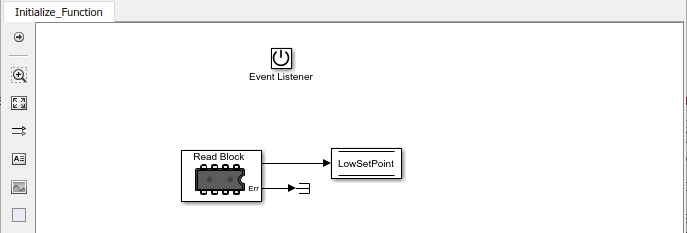

Here is the NvMServiceCaller block dialog box for the `ReadBlock` call in the Initialize Function block. For more information, see [NvMServiceCaller](docid:autosar_ref.bvczlrr-1).

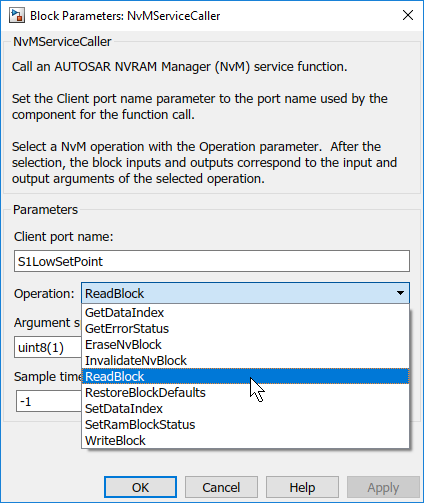

Sensor components `autosar_bsw_sensor1` and `autosar_bsw_sensor2` each contain two calls to the Dem service interface `DiagnosticMonitor`. Both calls are implemented using the Basic Software library block [DiagnosticMonitorCaller](docid:autosar_ref#bvczlg4-1). Each block is configured to call the `DiagnosticMonitor` operation `SetEventStatus`. The `SetEventStatus` calls use client ports `S1StuckLow`, `S1StuckHigh`, `S2StuckLow`, and `S2StuckHigh`.

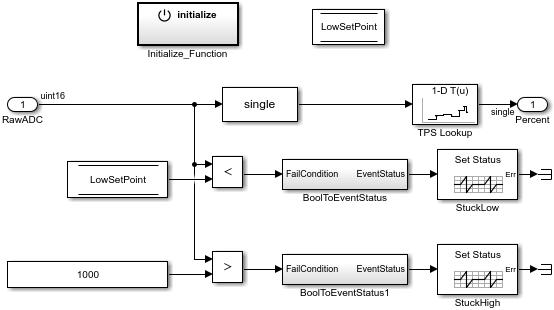

Here is the DiagnosticMonitorCaller block dialog box for the `StuckLow` call in the first sensor component. For more information, see [DiagnosticMonitorCaller](docid:autosar_ref.bvczlg4-1).

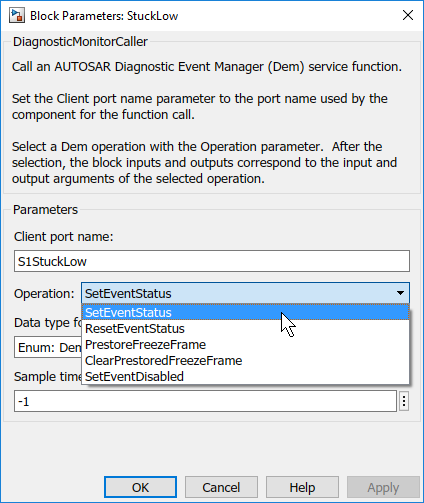

Monitor component `autosar_bsw_monitor` contains a call to the Dem service interface `DiagnosticMonitor` and four calls to the Dem service interface `DiagnosticInfo`.

- As in the sensor component, a `DiagnosticMonitorCaller` block implements the `DiagnosticMonitor` call, and it is configured to call the `SetEventStatus` operation. The client port name is `TPS`.

- The four `DiagnosticInfo` calls are implemented using the Basic Software library block [DiagnosticInfoCaller](docid:autosar_ref.bvczj76-1). Each block is configured to call the `DiagnosticInfo` operation `GetEventFailed`. The `GetEventFailed` calls use client ports `TPS1StuckLow`, `TPS1StuckHigh`, `TPS2StuckLow`, and `TPS2StuckHigh`.

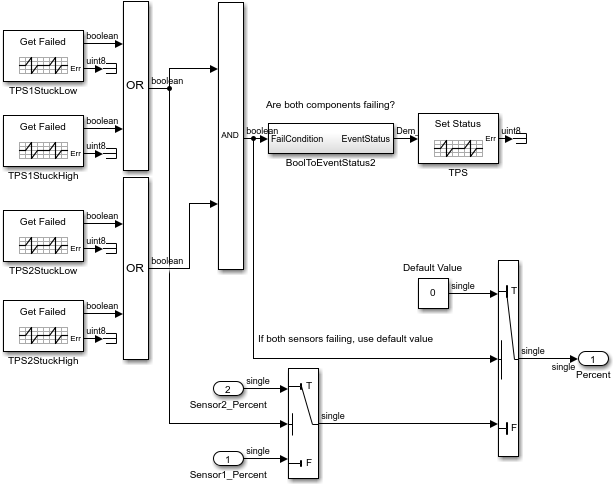

Here is the `DiagnosticinfoCaller` block dialog box for the `TPS1StuckLow` call. For more information, see [DiagnosticInfoCaller](docid:autosar_ref.bvczj76-1).

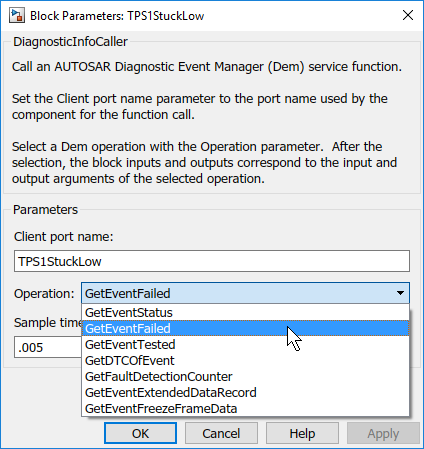

If you have Simulink Coder and Embedded Coder software, you can generate C code and export ARXML descriptions for the NvM and Dem service calls. Open and build each component model. For example, to build model `autosar_bsw_monitor`, open the model. Press **Ctrl+B** or enter the MATLAB command `slbuild('autosar_bsw_monitor')`.

To see the results of the model build, examine the code generation report.

## Configure Reference Implementations of AUTOSAR Basic Software Services for Simulation

To simulate an AUTOSAR component model that calls BSW services, create a containing composition, system, or harness model. In that containing model, provide reference implementations of the NvM, Dem, and FiM service operations called by the component.

The AUTOSAR Basic Software block library includes an [NVRAM Service Component](docid:autosar_ref.bvczlz2-1mem) block and a [Diagnostic Service Component](docid:autosar_ref.bvczlz2-1diag) block. The blocks provide reference implementations of NvM, Dem, and FiM service operations. To support simulation of component calls to the NvM, Dem, and FiM services, include the blocks in the containing model. You can insert the blocks in either of two ways:

- Automatically insert the blocks by creating a Simulink Test harness model

- Manually insert the blocks into a containing composition, system, or harness model

To automatically insert Service Component blocks for a model that calls BSW NvM, Dem, and FiM services, open the model (or a containing model) and create a Simulink Test test harness (requires Simulink Test). For more information, see [Create a Test Harness](docid:sltest_gs.mw_04775204-160d-4669-b0cf-d431225b3cdb). Creating a test harness compiles the model, adds the Service Component blocks, and creates ports and other elements required for simulation. 

This example manually inserts Service Component blocks for NvM and Dem service calls. Open the integration model `autosar_bsw_presim`. Using the Library Browser or `add_block` commands, or by typing block names in the model window, add the NVRAM and Diagnostic Service Component blocks to the model.

open_system('autosar_bsw_presim');
add_block('autosarlibnvm/NVRAM Service Component','autosar_bsw_presim/NVRAM Service Component');
add_block('autosarlibdem/Diagnostic Service Component','autosar_bsw_presim/Diagnostic Service Component');
set_param('autosar_bsw_presim','SimulationCommand','update');

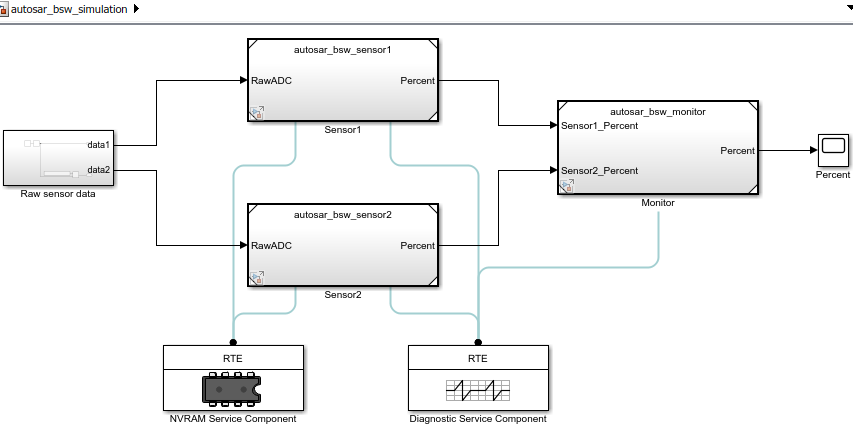

The NVRAM Service Component block has prepopulated parameters, including run-time environment (RTE) parameters and **NVRAM Properties** parameters. Examine the parameter settings and consider if any require modifying, based on how you are using the NvM service operations. For more information, see [NVRAM Service Component](docid:autosar_ref.bvczlz2-1mem).

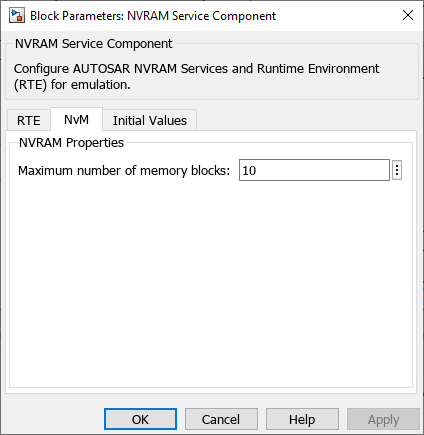

The RTE tab table lists component client ports and their mapping to NvM service block IDs. Each row in the table represents a call into NvM services from a Basic Software caller block. Calls that act on the same NvM block typically use the same block ID. This example maps the NvM `ReadBlock` client ports to different block IDs.

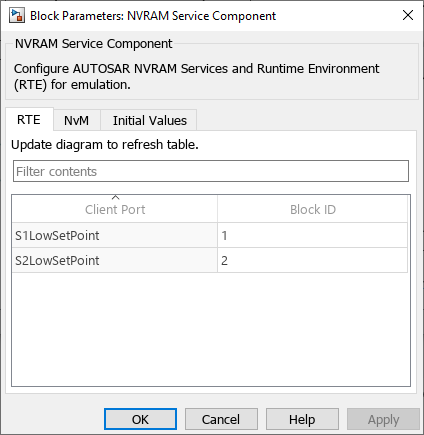

The Initial Values tab table lists component client ports and their initial values for simulation. The default initial value is 0.

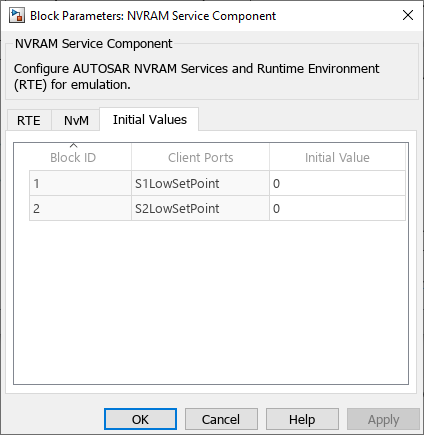

The Diagnostic Service Component block has prepopulated parameters, including RTE parameters and Dem **Counter-Based Debouncing** parameters. Examine the parameter settings and consider if any require modifying, based on how you are using the Dem service operations.

The **Counter-Based Debouncing** parameters control the counter-based debounce algorithm provided by the Dem service reference implementations. During multiple simulation runs, you can tune event step size and threshold parameters and observe the effects. For more information, see [Diagnostic Service Component](docid:autosar_ref.bvczlz2-1diag).

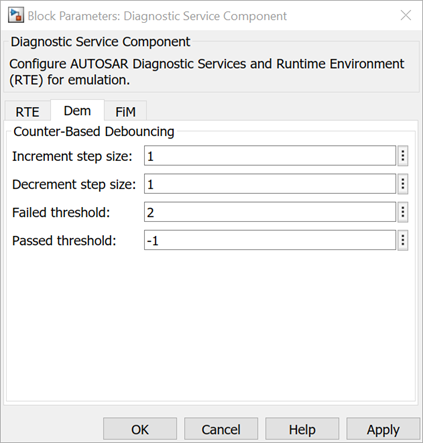

The RTE tab table lists component client ports and their mapping to Dem or FiM service IDs (in this example, event IDs). Each row in the table represents a call into Dem services from a Basic Software caller block. Calls that act on the same event typically use the same event ID. This example maps the Dem `SetEventStatus` client ports to different event IDs, and then maps the Dem `GetEventFailed` client ports to event IDs that are shared with `SetEventStatus` ports. For example, `SetEventStatus` port `S1StuckHigh` and `GetFailedEvent` port `TPS1StuckHigh` share event ID 1; `S1Stucklow` and `TPS1StuckLow` share event ID 2; and so on.

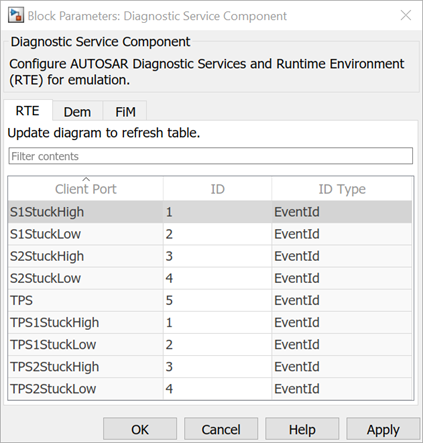

## Simulate Calls to AUTOSAR NvM and Dem Services

After configuring NVRAM and Diagnostic Service Component blocks in the integration model, simulate the model. The simulation exercises the AUTOSAR NvM and Dem service calls in the throttle position sensor and monitor component models.

open_system('autosar_bsw_simulation');
simOutIntegration = sim('autosar_bsw_simulation');

## Related Links

- [Model AUTOSAR Basic Software Service Calls](docid:autosar_ug.bvh674b-1)

- [Configure Calls to AUTOSAR NVRAM Manager Service](docid:autosar_ug.bvh7all-1)

- [Configure Calls to AUTOSAR Diagnostic Event Manager Service](docid:autosar_ug.bvfx3up-1)

- [Configure AUTOSAR Basic Software Service Implementations for Simulation](docid:autosar_ug.mw_b97bc016-9a16-43c7-acf9-801b65b75f32)

Copyright 2020 The MathWorks, Inc.